% 生成稠密的数据点
num_points = 200;
bound = 5

bound = 5

x1 = linspace(-bound, bound, num_points);
x2 = linspace(-bound, bound, num_points);
[X1, X2] = meshgrid(x1, x2);
input = [X1(:) X2(:)];

% 对每个数据点进行分类
% 假定w=[1 1 1]， threshold=0.5

threshold = 0.5

threshold = 0.5000

a = 1

a = 1

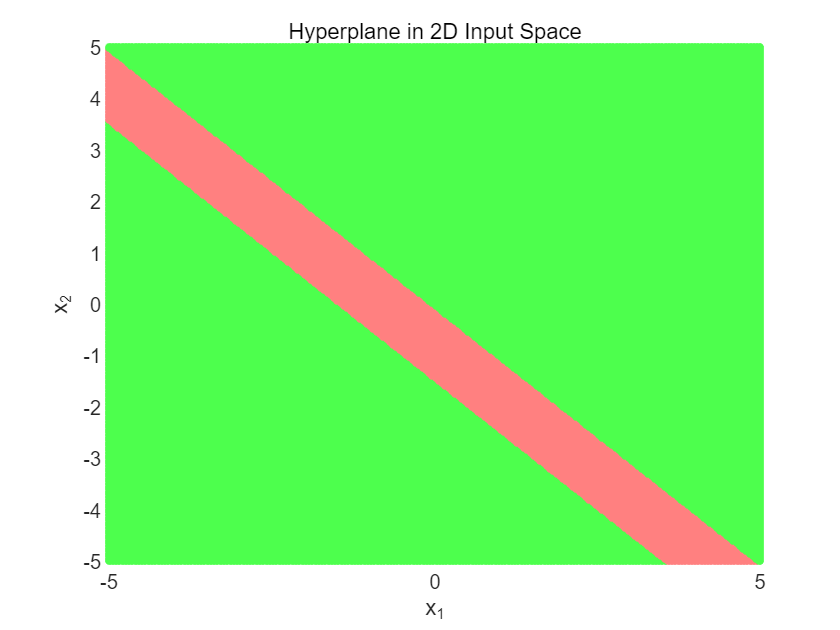

output = zeros(size(X1));
for i = 1:size(X1, 1)
    for j = 1:size(X1, 2)
        output(i, j) = distinguish(get_function_res(X1(i, j),X2(i, j), a), threshold, a);
    end
end

% 将输出矩阵转换为向量
output_vector = reshape(output, [], 1);

% 根据分类结果生成颜色矩阵，用颜色来区分。
colors = zeros(num_points^2, 3);
for i = 1:length(output_vector)
    if output_vector(i) == 1 % 正类
        colors(i, :) = [0.3 1 0.3]; % 浅浅的绿色
    else % 负类
        colors(i, :) = [1 0.5 0.5]; % 更浅一点的红色
    end
end

% 绘制超平面
figure;
scatter(input(:,1), input(:,2), 20, colors, 'filled');
hold on;

% 调整坐标轴，-1~1范围。
axis([-bound bound -bound bound]);

% 绘制线
% t = -1:0.01:1
% y = sigmoid(t, a)

% 添加标题和标签
title('Hyperplane in 2D Input Space');
xlabel('x_1');
ylabel('x_2');


% 标记正类和负类
%legend('Positive Class', 'Negative Class');

% 显示图例
%legend('show');


bound = 10

bound = 10

x1_range = linspace(-bound, bound, 200)

x1_range =   -10.0000   -9.8995   -9.7990   -9.6985   -9.5980   -9.4975   -9.3970   -9.2965   -9.1960   -9.0955   -8.9950   -8.8945   -8.7940   -8.6935   -8.5930   -8.4925   -8.3920   -8.2915   -8.1910   -8.0905   -7.9899   -7.8894   -7.7889   -7.6884   -7.5879   -7.4874   -7.3869   -7.2864   -7.1859   -7.0854   -6.9849   -6.8844   -6.7839   -6.6834   -6.5829   -6.4824   -6.3819   -6.2814   -6.1809   -6.0804   -5.9799   -5.8794   -5.7789   -5.6784   -5.5779   -5.4774   -5.3769   -5.2764   -5.1759   -5.0754


x2_range = linspace(-bound, bound, 200)

x2_range =   -10.0000   -9.8995   -9.7990   -9.6985   -9.5980   -9.4975   -9.3970   -9.2965   -9.1960   -9.0955   -8.9950   -8.8945   -8.7940   -8.6935   -8.5930   -8.4925   -8.3920   -8.2915   -8.1910   -8.0905   -7.9899   -7.8894   -7.7889   -7.6884   -7.5879   -7.4874   -7.3869   -7.2864   -7.1859   -7.0854   -6.9849   -6.8844   -6.7839   -6.6834   -6.5829   -6.4824   -6.3819   -6.2814   -6.1809   -6.0804   -5.9799   -5.8794   -5.7789   -5.6784   -5.5779   -5.4774   -5.3769   -5.2764   -5.1759   -5.0754


[X1, X2] = meshgrid(x1_range, x2_range)

X1 =   -10.0000   -9.8995   -9.7990   -9.6985   -9.5980   -9.4975   -9.3970   -9.2965   -9.1960   -9.0955   -8.9950   -8.8945   -8.7940   -8.6935   -8.5930   -8.4925   -8.3920   -8.2915   -8.1910   -8.0905   -7.9899   -7.8894   -7.7889   -7.6884   -7.5879   -7.4874   -7.3869   -7.2864   -7.1859   -7.0854   -6.9849   -6.8844   -6.7839   -6.6834   -6.5829   -6.4824   -6.3819   -6.2814   -6.1809   -6.0804   -5.9799   -5.8794   -5.7789   -5.6784   -5.5779   -5.4774   -5.3769   -5.2764   -5.1759   -5.0754
  -10.0000   -9.8995   -9.7990   -9.6985   -9.5980   -9.4975   -9.3970   -9.2965   -9.1960   -9.0955   -8.9950   -8.8945   -8.7940   -8.6935   -8.5930   -8.4925   -8.3920   -8.2915   -8.1910   -8.0905   -7.9899   -7.8894   -7.7889   -7.6884   -7.5879   -7.4874   -7.3869   -7.2864   -7.1859   -7.0854   -6.9849   -6.8844   -6.7839   -6.6834   -6.5829   -6.4824   -6.3819   -6.2814   -6.1809   -6.0804   -5.9799   -5.8794   -5.7789   -5.6784   -5.5779   -5.4774   -5.3769   -5.2764   -5.1759   -

X2 =   -10.0000  -10.0000  -10.0000  -10.0000  -10.0000  -10.0000  -10.0000  -10.0000  -10.0000  -10.0000  -10.0000  -10.0000  -10.0000  -10.0000  -10.0000  -10.0000  -10.0000  -10.0000  -10.0000  -10.0000  -10.0000  -10.0000  -10.0000  -10.0000  -10.0000  -10.0000  -10.0000  -10.0000  -10.0000  -10.0000  -10.0000  -10.0000  -10.0000  -10.0000  -10.0000  -10.0000  -10.0000  -10.0000  -10.0000  -10.0000  -10.0000  -10.0000  -10.0000  -10.0000  -10.0000  -10.0000  -10.0000  -10.0000  -10.0000  -10.0000
   -9.8995   -9.8995   -9.8995   -9.8995   -9.8995   -9.8995   -9.8995   -9.8995   -9.8995   -9.8995   -9.8995   -9.8995   -9.8995   -9.8995   -9.8995   -9.8995   -9.8995   -9.8995   -9.8995   -9.8995   -9.8995   -9.8995   -9.8995   -9.8995   -9.8995   -9.8995   -9.8995   -9.8995   -9.8995   -9.8995   -9.8995   -9.8995   -9.8995   -9.8995   -9.8995   -9.8995   -9.8995   -9.8995   -9.8995   -9.8995   -9.8995   -9.8995   -9.8995   -9.8995   -9.8995   -9.8995   -9.8995   -9.8995   -9.8995   -

a = 0.4495

a = 0.4495

threshold = 0.5

threshold = 0.5000

figure
var1 = 4./(1+exp(-a*(3*X1+3*X2+1)));
var2 = 5./(1+exp(-a*(3*X1+3*X2+4)));
out = var1-var2+2.0

out =     2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000
    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000    2.0000   

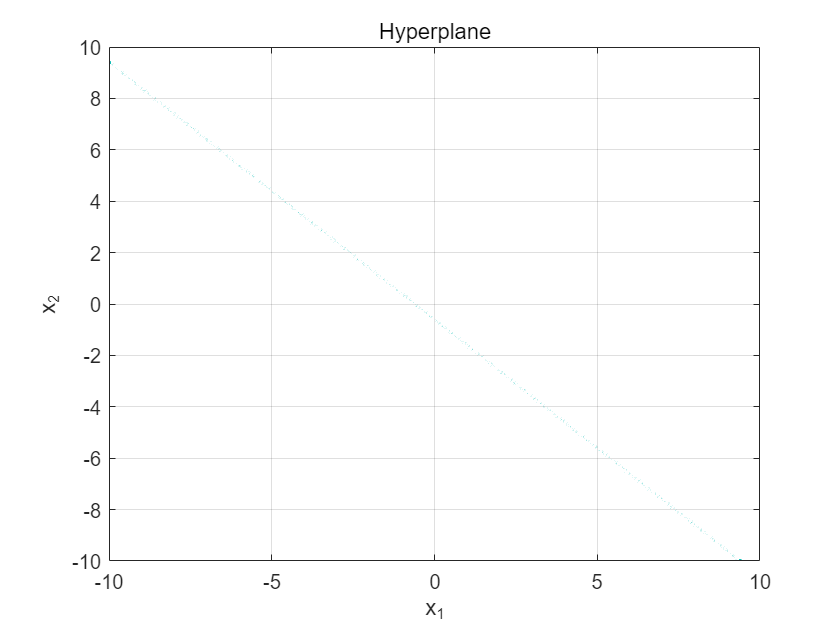

contour(X1, X2, out, [0 0], 'LineWidth', 2)
title('Hyperplane')
xlabel('x_1')
ylabel('x_2')
grid on

function out = distinguish(v, threshold, a)
    var = 1/(1+exp(-a*v));
    out = 1;
    if var < threshold
        out = 0;
    end
    %if v < 0
        %out = 0;
    %end
end   

function out = sigmoid(x, a)
    out = 1./(1+exp(-a*x));
end

function out = get_function_res(x1, x2, a)
    var1 = 4/(1+exp(-a*(3*x1+3*x2+1)));
    var2 = 5/(1+exp(-a*(3*x1+3*x2+4)));
    out = var1-var2+2;
end